clear all;

tr = 0.15;
Mp = 0.2;

wn = 1.8/tr;
delta = (log(1/Mp))/(sqrt((pi^2)+(log(1/Mp)^2)));
ts = 3/(delta*wn);
wb = 1.8/tr;
phase_margin = atan((2*delta)/(sqrt((sqrt(1+(4*(delta)^4)))-(2*(delta)^2))));
Tl=1/(5*wb);

A = [0 1; 0 -10];
B = [0; 120];
C = [1 0];
D = 0;

[num, den] = ss2tf(A,B,C,D);
P = tf(num,den);
[mod_P,phase] = bode(P,wb);

phase_P = phase/180 * pi;
delta_phi = -pi + phase_margin - phase_P;
delta_k = 1/mod_P;
alpha = 4;
Tw = ts/5;
Kw = 1/Tw; %3.5;

Td = (tan(delta_phi)+sqrt((tan(delta_phi))^2+(4/alpha)))/(2*wb);
Ti = alpha*Td;

Kp = delta_k*cos(delta_phi);
Kd = Kp*Td;
Ki = Kp/Ti;

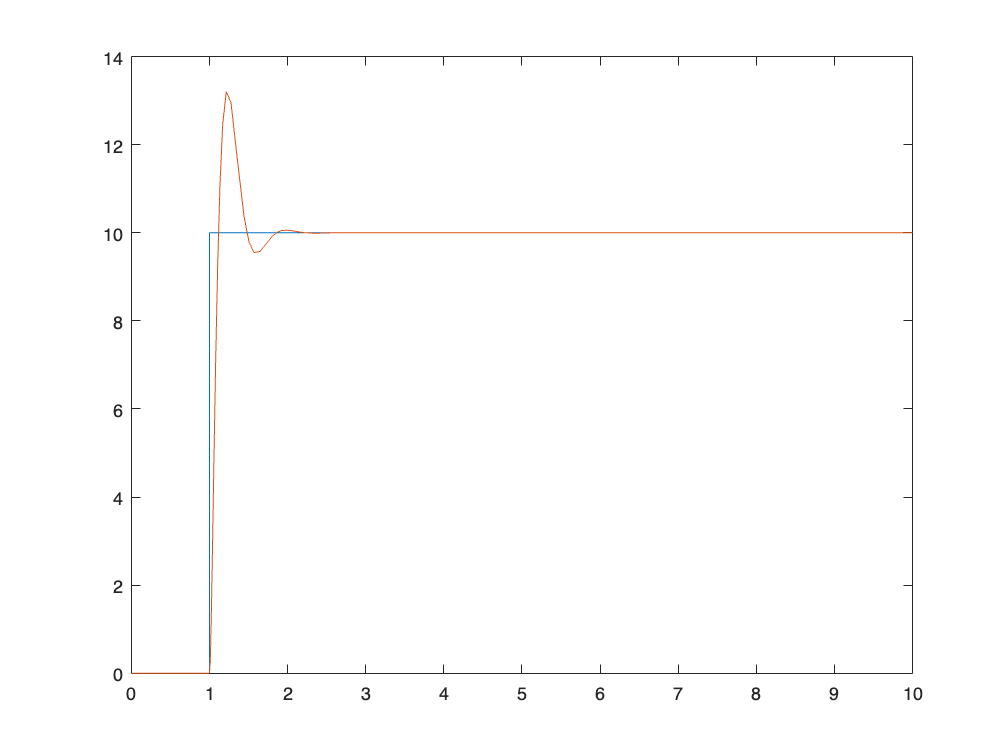

sw_sat = 1; %OFF
sw_aw = 1; %OFF
simulation = sim("Prova_es1_sim.slx",'StopTime', '10');

time = simulation.simulation.time;

figure;
plot(time, simulation.simulation.signals.values);

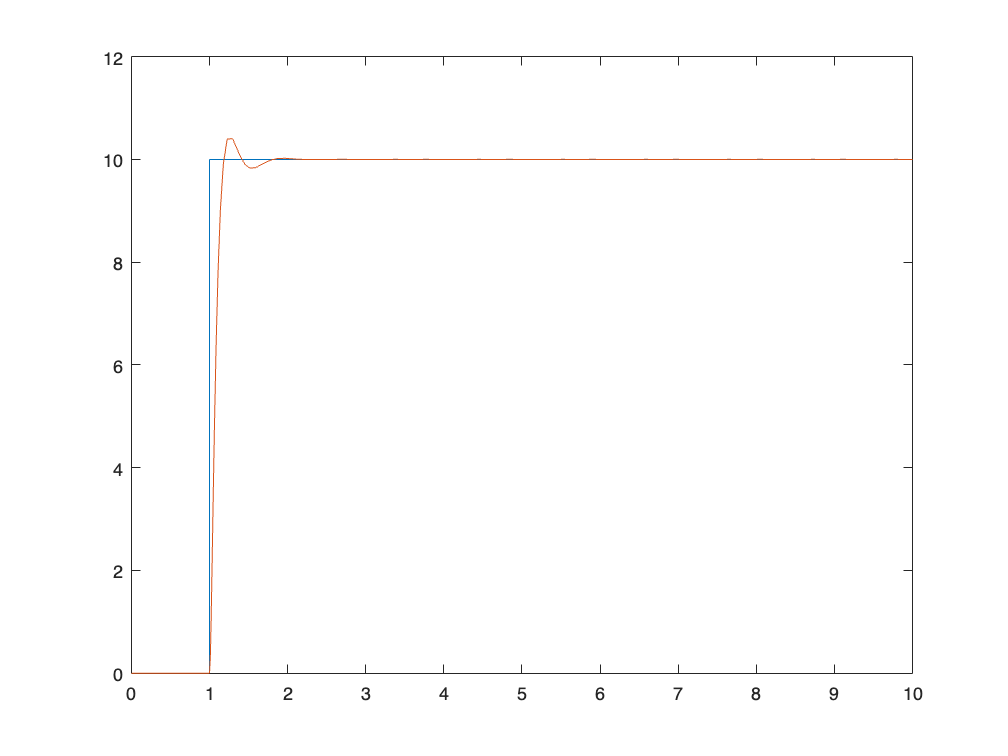

sw_sat = 1; %OFF
sw_aw = 2; %ON
simulation = sim("Prova_es1_sim.slx",'StopTime', '10');

time = simulation.simulation.time;

figure;
plot(time, simulation.simulation.signals.values);

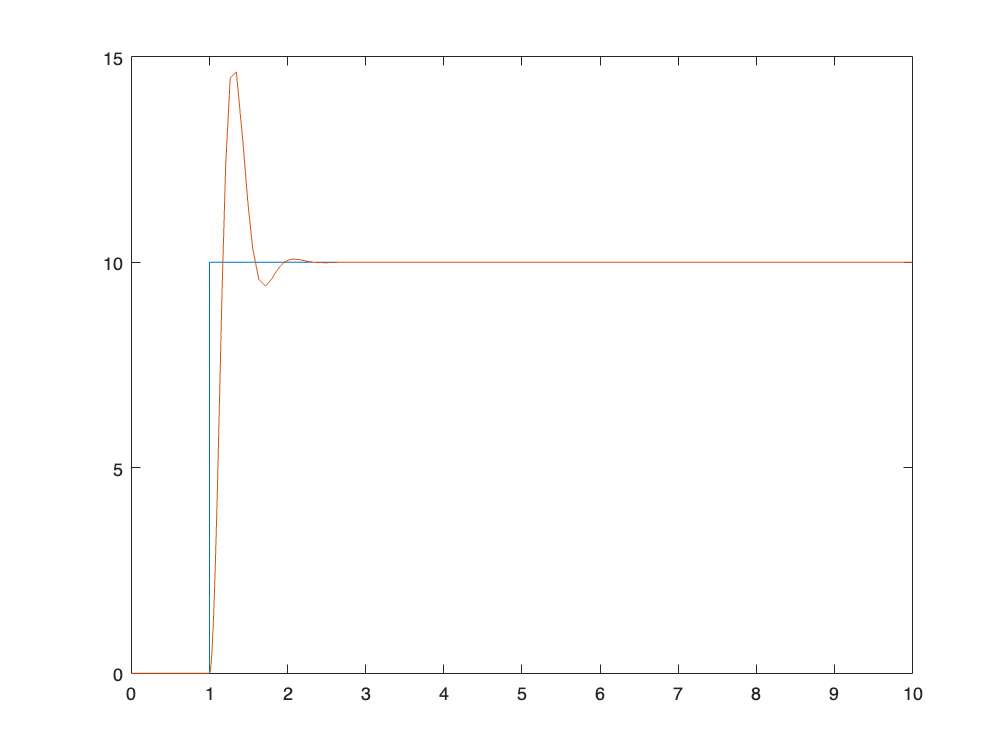

sw_sat = 2; %ON
sw_aw = 1; %OFF
simulation = sim("Prova_es1_sim.slx",'StopTime', '10');

time = simulation.simulation.time;

figure;
plot(time, simulation.simulation.signals.values);

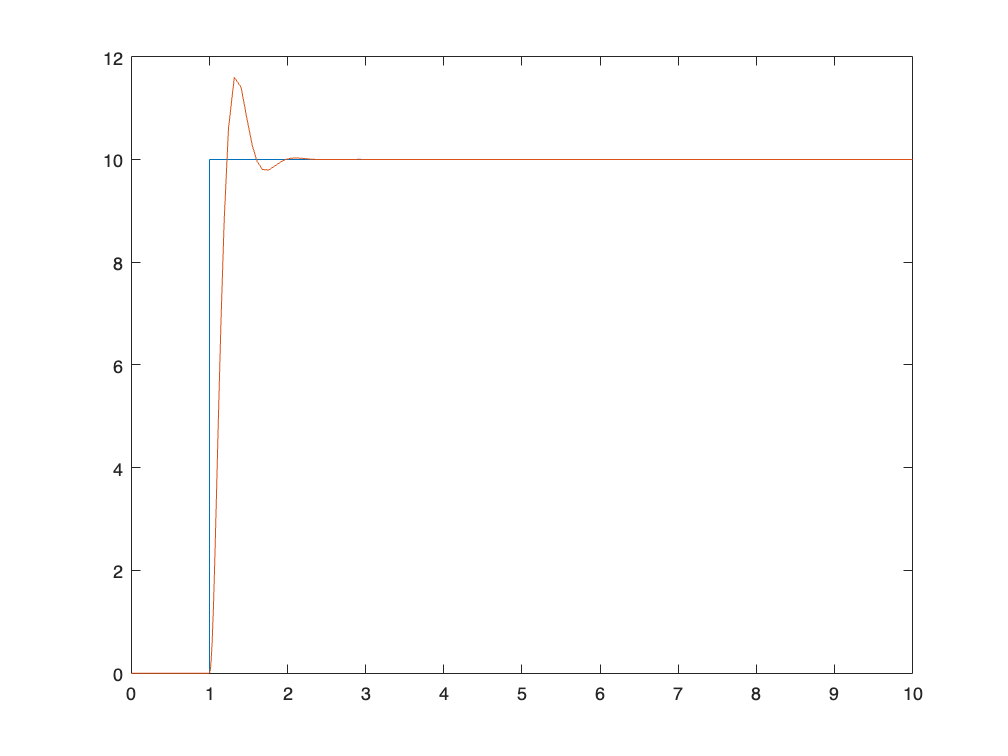

sw_sat = 2; %ON
sw_aw = 2; %ON
simulation = sim("Prova_es1_sim.slx",'StopTime', '10');

time = simulation.simulation.time;

figure;
plot(time, simulation.simulation.signals.values);